clc; clear all;

%%1.1
% Orbit Parameter
a = 7078;    %[km]
e = 0.001;   %[-]
inc =97.8;   %[deg]
raan = 80;   %[deg]
aop = 0;     %[deg]
f = 0;       %[deg]true anomaly

lat = 37.383981;      % [deg] 위도 
lon = 126.657319;     % [deg] 경도
commu_angle = 10;      % [deg] 최소 교신각

startTime = datetime(2026,4,9,0,0,0,'TimeZone','UTC');
stopTime  = startTime + hours(24);
sampleTime = 10; % sec

sc = satelliteScenario(startTime, stopTime, sampleTime);

% 궤도 요소로 위성 추가
% (a, e, i, RAAN, omega, trueAnomaly)
sat = satellite(sc, a*1e3, e, inc, raan, aop, f, ...
    'OrbitPropagator', 'two-body-keplerian', 'Name', 'LEO-Sat');

% 지상국 추가
gs = groundStation(sc, 37.383981, 126.657319, ...
    'MinElevationAngle', commu_angle);

% 접촉 분석
ac = access(gs, sat);
intvls = accessIntervals(ac);  % 교신 구간 테이블로 출력

disp(intvls);

          Source           Target      IntervalNumber         StartTime               EndTime          Duration    StartOrbit    EndOrbit
    __________________    _________    ______________    ___________________    ___________________    ________    __________    ________
    "Ground station 2"    "LEO-Sat"          1           2026-04-09 06:41:40    2026-04-09 06:50:10      510            5            5   
    "Ground station 2"    "LEO-Sat"          2           2026-04-09 08:20:20    2026-04-09 08:27:00      400            6            6   
    "Ground station 2"    "LEO-Sat"          3           2026-04-09 18:44:00    2026-04-09 18:48:00      240           12           12   
    "Ground station 2"    "LEO-Sat"   

### 1.1 24시간 동안 교신 가능 시간을 분석하시오. 교신 가능 횟수와 함께 교신 구간별 진입 시간, 탈출 시간 패스 별 교신 길이를 각각 구하시오.

MATLAB에서 제공하는 Aerospace Toolbox를 통해서 24시간 동안 Sample Time을 10초로 설정하여 시뮬레이션을 진행하고, 최소교신각을 문제에 주어진 값인 10deg로 하여 교신 파라미터를 구한 결과는 intvls로 저장하였고 출력결과는 다음과 같다.

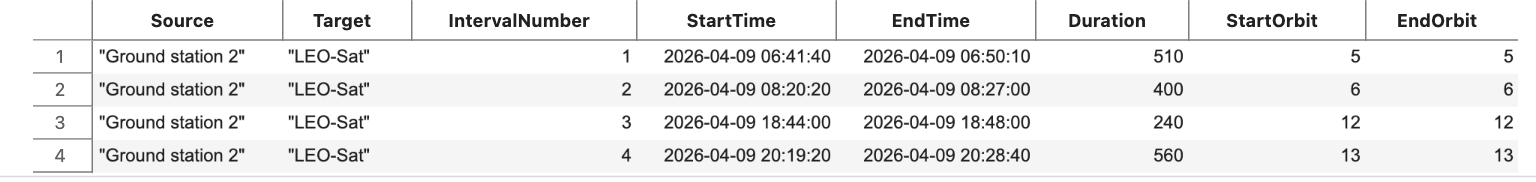

결과에서 알 수 있듯이 교신 가능 횟수는 24시간 중 총 4회이며, 교신 구간별 진입 시간은 StartTime, 탈출시간은 EndTime, 교신 길이는 Duration이고 길이의 단위는 sec이다. 또한 1.2 문제를 해결하기 위해서 가장 긴 교신 패스는 4번째 접속일 때 이므로 4번쨰 교신값들을 사용하였다. 

%1.2
t_start = intvls.StartTime(4);
t_mid = intvls.StartTime(4) + seconds(intvls.Duration(4) / 2);
t_end = intvls.EndTime(4);

timeList = [t_start, t_mid, t_end];
sat_gs_dist = zeros(3,3); %각 지점에서 위성과 지상국에 대한 상대정보

for j = 1:3
    [az, elv, range] = aer(gs, sat, timeList(j));
    sat_gs_dist(j, :) = [az, elv, range/1e3]; 
end
disp(sat_gs_dist(:,3));  % [km]

       2188.2
       827.35
       2154.6



%링크버짓분석에 필요한 파라미터
Gt = 0; %dBi
P = 1; %W -> log로 변환해야 한다. 
Ll = 0;
epsilon_t = 10; %deg
theta_t = 30; %deg
epsilon_r = 1; %deg
theta_r = 4; %deg
c = 299792458; %m/s
f = 435*10^6; %Hz
D = 2.4;
eta = 0.6;
Ts = 300;
R = 64*10^3; %bps
L_imp = 0;

link_margin = zeros(3,1);


for i = 1:3
    d = sat_gs_dist(i,3);
    link_margin(i) = compute_linkmargin(Gt, P, Ll, epsilon_t, epsilon_r , ...
    theta_t, theta_r, c, d*1e3, f, D, eta, Ts, R, L_imp, timeList(i));
end

 Time : 2026-04-09 20:19:20
EIRP : 0.000000
Lpt : -1.333333
Ls : -152.019471
Lpr : -0.750000
Gr : 18.565522
G/T : -6.205690
Eb/N0 : 20.229705
LM : 13.229705

 Time : 2026-04-09 20:24:00
EIRP : 0.000000
Lpt : -1.333333
Ls : -143.571302
Lpr : -0.750000
Gr : 18.565522
G/T : -6.205690
Eb/N0 : 28.677875
LM : 21.677875

 Time : 2026-04-09 20:28:40
EIRP : 0.000000
Lpt : -1.333333
Ls : -151.885076
Lpr : -0.750000
Gr : 18.565522
G/T : -6.205690
Eb/N0 : 20.364100
LM : 13.364100






% Calculate Link Margin Function
function LM = compute_linkmargin(Gt, P, Ll, epsilon_t, epsilon_r , ...
    theta_t, theta_r, c, d, f, D, eta, Ts, R, L_imp, t)
    %단위는 dB스케일로 통일한다. 

    EIRP = 10*log10(P) + Gt + Ll;
    Lpt = -12*(epsilon_t/theta_t)^2;
    Lpr = -12*(epsilon_r/theta_r)^2;
    Ls = 20*log10(c) - 20*log10(4*pi) - 20*log10(d) - 20*log10(f);
    Gr = -159.59 + 20*log10(D) + 20*log10(f) + 10*log10(eta);
    G_T_dBi = Gr - 10*log10(Ts);
    ideal_Eb_N0 = EIRP +Lpr + Lpt + Ls+ G_T_dBi +228.6 - 10*log10(R);
 
    LM = ideal_Eb_N0 - 7 + L_imp;
    
    fprintf(' Time : %s\n', datestr(t, 'yyyy-mm-dd HH:MM:SS'));
    fprintf("EIRP : %f\n", EIRP);
    fprintf("Lpt : %f\n", Lpt);
    fprintf("Ls : %f\n", Ls);
    fprintf("Lpr : %f\n", Lpr);
    fprintf("Gr : %f\n", Gr);
    fprintf("G/T : %f\n", G_T_dBi);
    fprintf("Eb/N0 : %f\n", ideal_Eb_N0);
    fprintf("LM : %f\n", LM);
    fprintf('========================================\n');
    fprintf('\n');

end


### 1.2 가장 긴 교신 패스를 선택하여 교신 직후, 중앙, 탈출 시점에서의 다운링크에 대한 링크  마진을 계산하시오. 

링크 마진을 계산하기 위해서 이전과제에서 주어진 Parameter를 사용하였으며, 위성과 지상국의 상대위치에 따라 상대적 거리 변수인 d가 변하기 때문에 d를 ToolBox를 통해서 구하였고, 통신 직후는 교신 시작시간, 중앙은 교신 시작이후 Duration의 절반이 지났을 때, 탈출 시점은 교신 종료 시간으로 시간을 설정하여 d를 계산하였고, sat_gs_dist의 세번째 칼럼에 저장하였다. 결과는 다음과 같고, 순서대로 직후, 중앙, 탈출 시의 값이다. (단위는 km이다.)

 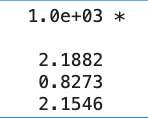

또한 링크 마진을 반복 계산하기 위해서 compute__linkmargin이라는 함수를 구현하여 위치에 따른 d차이에 따라 분석하였고, 결과는 다음과 같다. 

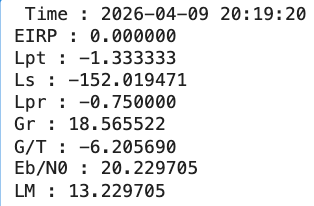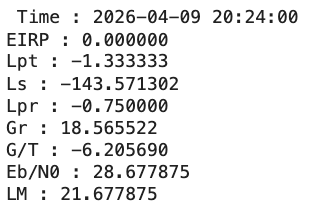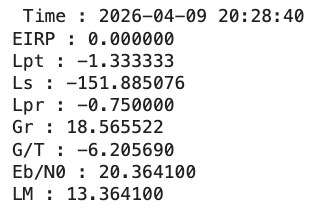

%1.3
analysis_t = t_start:seconds(10):t_end; %10초 간격으로 분석할 시간을 설정
N = length(analysis_t);

sat_gs_dynamic_dist = zeros(N,3);
dynamic_link_margin = zeros(N,1);

for j = 1:N
    [az, elv, range] = aer(gs, sat, analysis_t(j));
    sat_gs_dynamic_dist(j, :) = [az, elv, range/1e3]; 
end

for i = 1:N
    d = sat_gs_dynamic_dist(i,3);
    dynamic_link_margin(i) = compute_linkmargin(Gt, P, Ll, epsilon_t, epsilon_r , ...
    theta_t, theta_r, c, d*1e3, f, D, eta, Ts, R, L_imp, analysis_t(i));
end

 Time : 2026-04-09 20:19:20
EIRP : 0.000000
Lpt : -1.333333
Ls : -152.019471
Lpr : -0.750000
Gr : 18.565522
G/T : -6.205690
Eb/N0 : 20.229705
LM : 13.229705

 Time : 2026-04-09 20:19:30
EIRP : 0.000000
Lpt : -1.333333
Ls : -151.754552
Lpr : -0.750000
Gr : 18.565522
G/T : -6.205690
Eb/N0 : 20.494625
LM : 13.494625

 Time : 2026-04-09 20:19:40
EIRP : 0.000000
Lpt : -1.333333
Ls : -151.482612
Lpr : -0.750000
Gr : 18.565522
G/T : -6.205690
Eb/N0 : 20.766564
LM : 13.766564

 Time : 2026-04-09 20:19:50
EIRP : 0.000000
Lpt : -1.333333
Ls : -151.203409
Lpr : -0.750000
Gr : 18.565522
G/T : -6.205690
Eb/N0 : 21.045768
LM : 14.045768

 Time : 2026-04-09 20:20:00
EIRP : 0.000000
Lpt : -1.333333
Ls : -150.916704
Lpr : -0.750000
Gr : 18.565522
G/T : -6.205690
Eb/N0 : 21.332472
LM : 14.332472

 Time

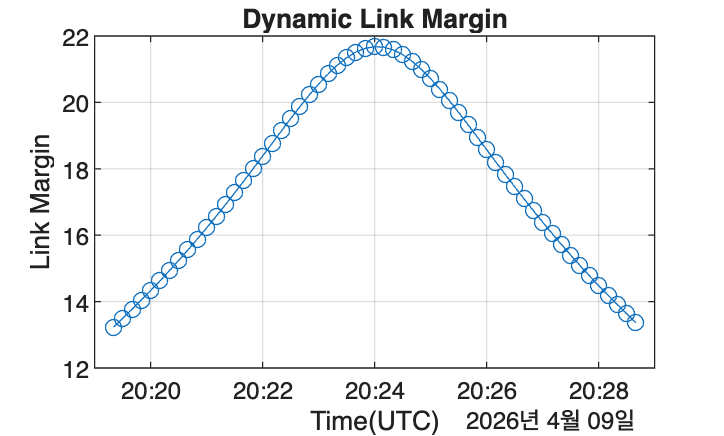


figure;
plot(analysis_t, dynamic_link_margin, '-o');
grid('on');
xlabel("Time(UTC)");
ylabel("Link Margin");
title("Dynamic Link Margin");

### 1.3 동적 환경에서의 링크 마진을 분석한다. 같은 교신 패스에 대해 10초 간격으로 링크 마진을 계산하고, 시간에 따른 링크 마진 변화를 그래프로 그리시오.

10초 간격으로 링크마진을 분석하기 위해서 analysis_t라는 분석 시간 테이블을 형성하였다. 1.2과 같은 과정을 통해서 각 시간에 따른 지상국과 위성의 상대적 거리를 구하고, 구현한 함수를 통해서 반복적으로 링크 마진을 계산한 결과는 dynamic_link_margin으로 저장하였다. 이를 Plot으로 도시한 결과는 다음과 같다. 교신을 시작하고 중간지점에서 거리가 가장 가까워 링크 마진이 증가함을 알 수 있다. 

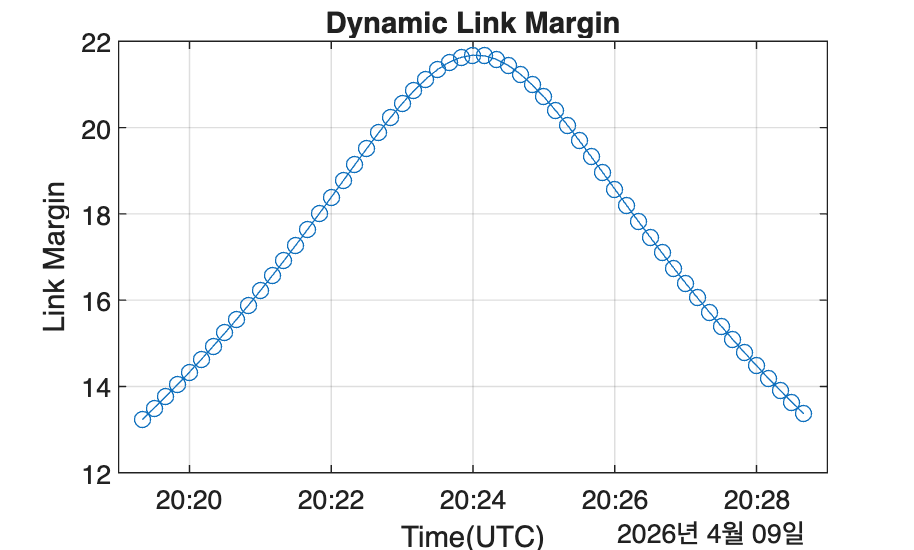

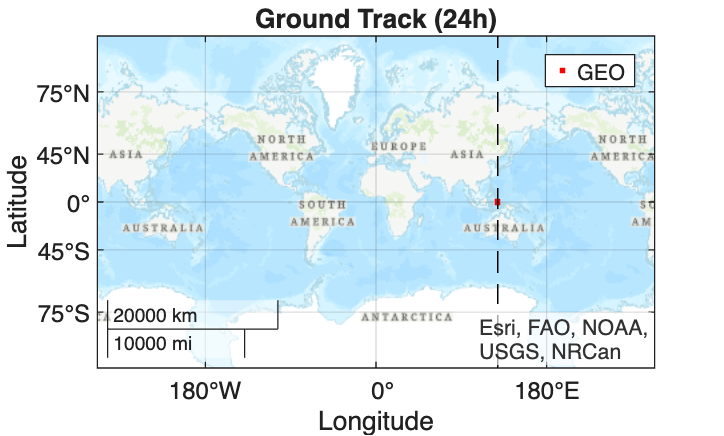

%2.1
mu_km  = 398600;       % [km^3/s^2]
T_sid  = 86164.0905;   % 항성일 [s]
a_GEO  = (mu_km * T_sid^2 / (4*pi^2))^(1/3); % [km]
inc_GEO  = 0;
e_GEO    = 0;
RAAN_GEO = 0;
AOP_GEO  = 0;

% GMST 계산
jd = juliandate(startTime);
T_century = (jd - 2451545.0) / 36525.0;
gmst_deg = mod( ...
    280.4606184 ...
    + 360.9856473662862 * (jd - 2451545.0) ...
    + 0.000387933 * T_century^2 ...
    - T_century^3 / 38710000, 360);

f0_GEO = mod(128.5 + gmst_deg, 360);

% 1차 생성 (임시 이름)
sat_GEO_temp = satellite(sc, a_GEO*1e3, e_GEO, inc_GEO, RAAN_GEO, AOP_GEO, f0_GEO, ...
    'OrbitPropagator', 'two-body-keplerian', 'Name', 'GEO-Sat-temp');

% 시작 시점 실제 경도 확인
[LLA_check, ~, ~] = states(sat_GEO_temp, startTime, 'CoordinateFrame', 'geographic');
lon_error = 128.5 - LLA_check(2);
f0_GEO = mod(f0_GEO + lon_error, 360);

% 임시 위성 삭제
delete(sat_GEO_temp);

% 보정된 f0로 최종 생성
sat_GEO = satellite(sc, a_GEO*1e3, e_GEO, inc_GEO, RAAN_GEO, AOP_GEO, f0_GEO, ...
    'OrbitPropagator', 'two-body-keplerian', 'Name', 'GEO-Sat');% 지상 궤적 시각화

[LLA_geo, ~, ~] = states(sat_GEO, 'CoordinateFrame', 'geographic');

figure;
geoplot(LLA_geo(1,:), LLA_geo(2,:), 'r.', ...
        [-90,90], [128.5,128.5], 'k--');
geobasemap topographic;
geolimits([-90 90], [-180 180]);
legend('GEO');
title('Ground Track (24h)');


fprintf('=== 2.1 GEO 궤도 설계 결과 ===\n');

=== 2.1 GEO 궤도 설계 결과 ===


fprintf('반장축 a_GEO = %.2f km\n', a_GEO);

반장축 a_GEO = 42164.15 km


fprintf('이심률 e = %.1f\n', e_GEO);

이심률 e = 0.0


fprintf('경사각 inc = %.1f deg\n', inc_GEO);

경사각 inc = 0.0 deg


fprintf('RAAN = %.1f deg\n', RAAN_GEO);

RAAN = 0.0 deg


fprintf('AOP = %.1f deg\n', AOP_GEO);

AOP = 0.0 deg


fprintf('초기 진근점이각 f0 = %.4f deg\n', f0_GEO);

초기 진근점이각 f0 = 325.4178 deg


fprintf('평균 경도 = %.3f deg\n', mean(LLA_geo(2,:)));

평균 경도 = 128.500 deg


fprintf('경도 표준편차 = %.3f deg\n', std(LLA_geo(2,:)));

경도 표준편차 = 0.000 deg


### 2.1 지구정지궤도위성은 128.5deg 경도 상공에 머무른다고 한다. 필요한 정지궤도위성의 초기 궤도 요소를 설계하고, 24시간 동안의 지상 궤적을 생성하여 궤도 설계가 제대로 수행되는지 확인하시오.

원형 적도 궤도이므로 이심률(e)와 경사각(i)는 0도가 된다. 또한 원궤도이므로 AOP(w)와 RAAN 또한 0으로 둘 수 있다. 그리고 정지궤도 위성의 경우 지구의 자전속도가 위성의 공전속도와 일치해야하므로, 항성일 기준 공전시간이 지구 자전시간과 동일해야한다. 이를 통해서 수식적으로 역산하여 장반경을 구할 수 있다. 또한 True Anomaly의 경우 ECI 기준으로 기술되고, 경도의 경우 ECEF에서 경도만큼 회전이므로, 자전각 + 경도를 해줘야 True Anomaly를 구할 수 있다. 라이브러리를 통해서 다음관계를 계산하였고, 계산된 정지궤도의 궤도파라미터는 다음과 같다. 

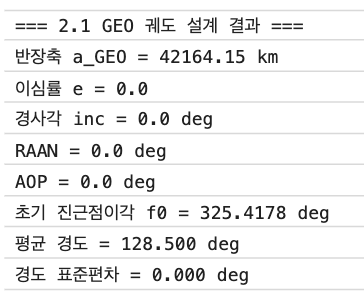

정지궤도위성의 궤도 설계가 잘되었음을 Ground Track을 통해서 알 수 있다.

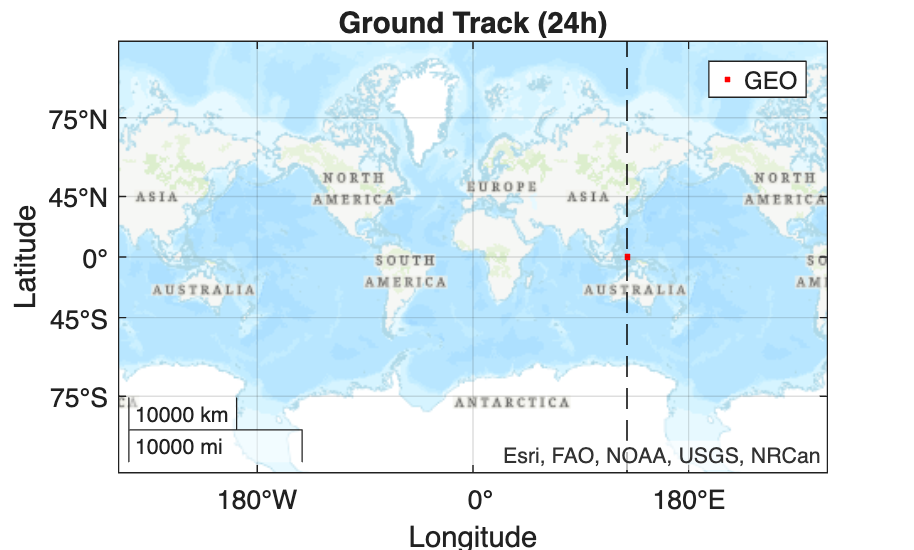

%2.2
ac_satcommu = access(sat, sat_GEO);
intvls_satcommu = accessIntervals(ac_satcommu);
disp(intvls_satcommu);

     Source       Target      IntervalNumber         StartTime               EndTime          Duration    StartOrbit    EndOrbit
    _________    _________    ______________    ___________________    ___________________    ________    __________    ________
    "LEO-Sat"    "GEO-Sat"           1          2026-04-09 00:07:20    2026-04-09 03:53:50     13590           1            3   
    "LEO-Sat"    "GEO-Sat"           2          2026-04-09 04:26:50    2026-04-09 05:27:50      3660           3            4   
    "LEO-Sat"    "GEO-Sat"           3          2026-04-09 06:06:10    2026-04-09 07:04:50      3520           4            5   
    "LEO-Sat"    "GEO-Sat"           4          2026-04-09 07:44:30    2026-04-09 0

### 2.2 문제 1번의 저궤도 위성과 문제 2.1에서 정의한 정지궤도 위성간의 교신 가능 횟수와  함께 교신 구간 별 진입, 탈출 시간과 교신 길이를 구하시오.

두 위성의 직선 경로가 지구에 의해 차폐되지만 않으면 교신 가능으로 판단하므로 최소 교신각은 따로 설정하지 않았으며, 두 위성의 접속 횟수는 24시간동안 총 13번이다. 또한 각 교신에 대한 진입 시간, 탈출 시간, 교신 길이는 다음 표와 같다. 진입 시간은 StartTime, 탈출시간은 EndTime, 교신 길이는 Duration으로 단위는 sec이다.

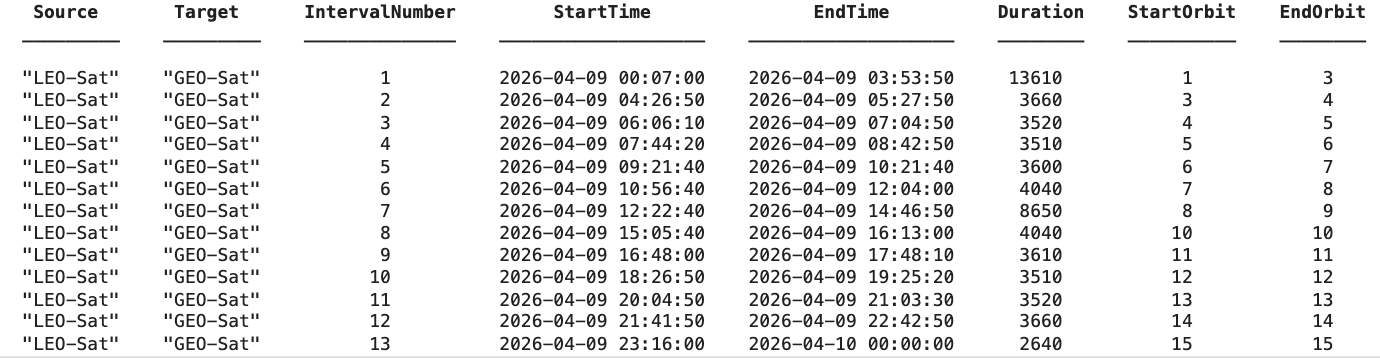

2.3에서 사용할 가장 긴 교신 시간을 갖는 교신은 첫번째 교신이다. 이를 2.3 풀이에 사용하겠다. 

%2.3
[~, idx_longest] = max(intvls_satcommu.Duration);
t_satcommu_start = intvls_satcommu.StartTime(idx_longest);
t_satcommu_mid   = intvls_satcommu.StartTime(idx_longest) + seconds(intvls_satcommu.Duration(idx_longest)/2);
t_satcommu_end   = intvls_satcommu.EndTime(idx_longest);

time_List_satcommu= [t_satcommu_start, t_satcommu_mid, t_satcommu_end];
G_T = -24.1;  % dB/K
f_hz = 1.575e9;  % Hz
R_bps = 3e3;  % bps

EIRP_cal = zeros(3,1);

for i = 1:3
    [~, ~, range] = aer(sat, sat_GEO, time_List_satcommu(i));  % sat_GEO → sat 방향
    EIRP_min = compute_min_EIRP(G_T, c, range, f_hz, R_bps, time_List_satcommu(i));
    EIRP_cal(i) = EIRP_min;
end

Time : 2026-04-09 00:07:20
Ls      : -189.4037 dB
G/T     : -24.1000 dB/K
EIRP_min: 29.6749 dBW
Time : 2026-04-09 02:00:35
Ls      : -188.7940 dB
G/T     : -24.1000 dB/K
EIRP_min: 29.0652 dBW
Time : 2026-04-09 03:53:50
Ls      : -189.4116 dB
G/T     : -24.1000 dB/K
EIRP_min: 29.6828 dBW



function EIRP_min = compute_min_EIRP(G_T, c, d, f, R, t)
    % G/T = -24.1 dB/K (주어진 값)
    % Free Space Loss만 고려 (나머지 손실 무시)
    
    Ls = 20*log10(c) - 20*log10(4*pi) - 20*log10(d) - 20*log10(f);
    
    Eb_N0_required = 7;   % dB
    LM = 3;               % dB
    k = 228.6;            % dBW/Hz/K (볼츠만)
    R_dB = 10*log10(R);   % dBbps
    
    % EIRP_min = Eb/N0 + LM - Ls - G/T - k + R
    EIRP_min = Eb_N0_required + LM - Ls - G_T - k + R_dB;
    
    fprintf('Time : %s\n', datestr(t, 'yyyy-mm-dd HH:MM:SS'));
    fprintf('Ls      : %.4f dB\n', Ls);
    fprintf('G/T     : %.4f dB/K\n', G_T);
    fprintf('EIRP_min: %.4f dBW\n', EIRP_min);
    fprintf('========================================\n');
end

fprintf('Final_EIRP_min: %.4f dBW\n', max(EIRP_cal));

Final_EIRP_min: 29.6828 dBW


### 2.3 가장 긴 교신 패스를 선택해 교신 직후, 중앙, 탈출 시점에서의 지구정지궤도위성 -> 저궤도위성 경로에 대한 3dB 링크 마진을 확보하고자 한다. 필요한 지구정지궤도위성 송신 안테나의 최소 EIRP를 구하시오.

Free Space Loss를 제외한 손실을 모두 무시하므로, 지향 오차에 의한 손실을 무시하고, 이에 따른 최소 EIRP를 구하는 코드인 EIRP_min 함수를 구현하여 구한 결과는 다음과 같다.

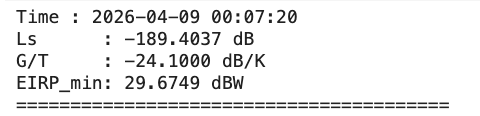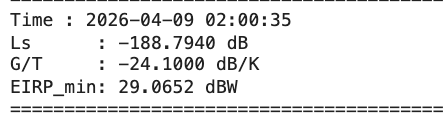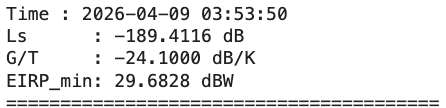

각각 순서대로 직후, 중앙, 탈출 시점에서의 결과이다. 만약 이 세 포인트로 EIRP를 결정해야 한다면 가장 worst case인 탈출 시점의 값이 **29.6828 dBW로 EIRP를 설계해야 한다**.

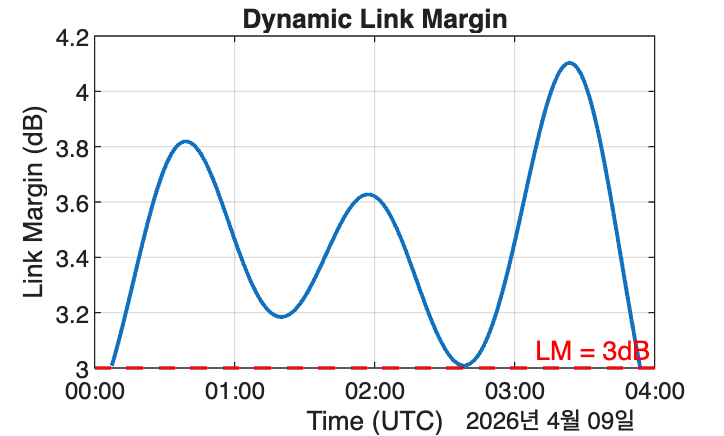

%2.4
t_satcommu_analysis = t_satcommu_start : seconds(10) : t_satcommu_end;
EIRP_fixed = max(EIRP_cal);  % dBW
N2 = length(t_satcommu_analysis);

link_margin_satcommu = zeros(N2,1);
dist_satcommu = zeros(N2,1);

for i = 1:N2
    [~, ~, range_satcommu] = aer(sat_GEO,sat, t_satcommu_analysis(i));
    dist_satcommu(i) = range_satcommu;
    link_margin_satcommu(i) = compute_LM_from_EIRP(EIRP_fixed, G_T, c, range_satcommu, f_hz, R_bps);
end

figure;
plot(t_satcommu_analysis, link_margin_satcommu, 'LineWidth', 1.5);
yline(3, '--r', 'LM = 3dB', 'LineWidth', 1.5);
xlabel('Time (UTC)');
ylabel('Link Margin (dB)');
title('Dynamic Link Margin');
grid on;



function LM = compute_LM_from_EIRP(EIRP, G_T, c, d, f, R)
    Ls = 20*log10(c) - 20*log10(4*pi) - 20*log10(d) - 20*log10(f);
    Eb_N0_required = 7;
    k = 228.6;
    R_dB = 10*log10(R);
    Eb_N0 = EIRP + Ls + G_T + k - R_dB;
    LM = Eb_N0 - Eb_N0_required;
end

### 2.4 동적 환경에서의 링크 마진을 분석한다. 같은 교신 패스에 대해 10초 간격으로 링크 마진을 계산하고 시간에 따른 마진 변화를 그래프로 그리시오.

2.3에서 항상 3dB의 마진을 유지하기 위해서 worst case인 29.6828 값을 이용하여 링크 마진을 계산하였다. 결과 그래프는 다음과 같다.

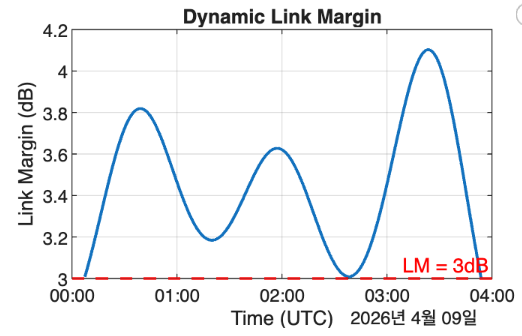

결과에서 알 수 있듯이 교신 구간 동안 3dB가 유지되며 거리에 따라 링크 마진이 변함을 확인할 수 있다.